clc
clear all
close all

## Constants Definition

delta_t=0.5;
time=linspace(0,300,300);
Omega_a=0.045;
Omega_b=-0.045;

qw=10;
W=qw*[2 0.05;0.05 0.5];

GamA=[0 0;1 0;0 0;0 1];
GamB=[0 0;1 0;0 0;0 1];


## PART A

A_mat = @(omega) [0 1 0 0;0 0 0 -omega;0 0 0 1;0 omega 0 0];
A_a = A_mat(Omega_a)

A_a =          0    1.0000         0         0
         0         0         0   -0.0450
         0         0         0    1.0000
         0    0.0450         0         0


A_b = A_mat(Omega_b)

A_b =          0    1.0000         0         0
         0         0         0    0.0450
         0         0         0    1.0000
         0   -0.0450         0         0



F_mat = @(omega, dt) [1, sin(omega * dt) / omega, 0, -(1 - cos(omega * dt)) / omega;
                      0, cos(omega * dt), 0, -sin(omega * dt);
                      0, (1 - cos(omega * dt)) / omega, 1, sin(omega * dt) / omega;
                      0, sin(omega * dt), 0, cos(omega * dt)];


Fa = F_mat(Omega_a, delta_t)

Fa =     1.0000    0.5000         0   -0.0056
         0    0.9997         0   -0.0225
         0    0.0056    1.0000    0.5000
         0    0.0225         0    0.9997


Fb = F_mat(Omega_b, delta_t)

Fb =     1.0000    0.5000         0    0.0056
         0    0.9997         0    0.0225
         0   -0.0056    1.0000    0.5000
         0   -0.0225         0    0.9997




Z = @(dt, A, gamma, W_mat) dt * [-A, gamma * W_mat * gamma'; zeros(4, 4), A'];

Za = Z(delta_t, A_a, GamA, W);
Zb = Z(delta_t, A_b, GamB, W);

e_za = expm(Za);
e_zb = expm(Zb);

FinvQA = e_za(1:4, 5:8);
Qa = (Fa')' * FinvQA

Qa =     0.8329    2.4983    0.0261    0.0953
    2.4983    9.9931    0.0719    0.3343
    0.0261    0.0719    0.2087    0.6266
    0.0953    0.3343    0.6266    2.5069



FinvQB = e_zb(1:4, 5:8);
Qb = (Fb')' * FinvQB

Qb =     0.8336    2.5011    0.0156    0.0297
    2.5011   10.0044    0.0531    0.1656
    0.0156    0.0531    0.2080    0.6238
    0.0297    0.1656    0.6238    2.4956


## PART B - i

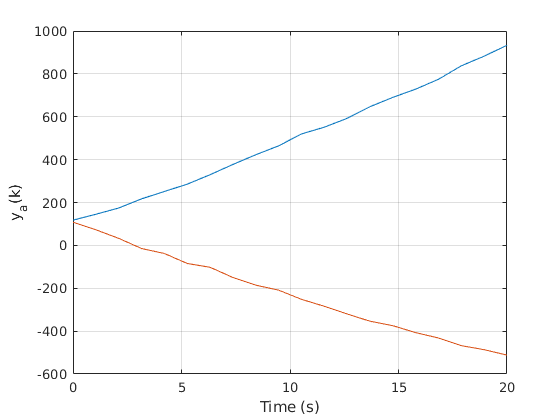

% set random number seed for consistency between runs
rng(100)

Ha=[1 0 0 0; 0 0 1 0];
Ra=[20 0.05; 0.05 20];

load('hw8problem1_data')
xa = xasingle_truth;

R_block = [];
H_block = [];

% generate noisy measurements 
for i = 1:length(xasingle_truth)
    noise = mvnrnd([0 0], Ra);
    y_k(:,i) = Ha * xasingle_truth(:,i) + noise';
end

figure(1)
time = linspace(0, 20, 20);
plot(time,y_k(:, 1:20))

xlabel('Time (s)')
ylabel('y_a(k)')
grid on

## PART B - ii

% initial mean and covariance guesses 
mu_a = [0 85 * cos(pi / 4), 0, -85 * sin(pi / 4)]';
P0_a = 900 * diag([10, 2, 10, 2]);

xm = mu_a;
Pm = P0_a;
K = zeros(4,2);

% Kalman Filter 
for i = 1:(length(xasingle_truth) - 1)
    % Prediction Step 
    xm(:, i+1) = Fa * xm(:, 1);
    Pm(:, :, i+1) = Fa * Pm(:,:,i) * Fa' + Qa;
    K(:, :, i+1) = Pm(:, :, i+1) * Ha' * inv(Ha * Pm(:,:,i+1) * Ha' + Ra);
    
    % Correction Step 
    xm(:, i+1) = xm(:, i+1) + K(:, :, i+1) * (y_k(:, i+1) - Ha * xm(:, i+1));
    Pm(:, :, i+1) = (eye(4) - K(:, :, i+1) * Ha) * Pm(i+1);
end


## PART C -- Setup

mu_a_0 = [0, 85 * cos(pi / 4), 0, -85 * sin(pi / 4)]; 
P_a_0 = 900 * diag([10, 2, 10, 2]); 
mu_b_0 = [3200, 85 * cos(pi / 4), 3200, -85 * sin(pi / 4)];
P_b_0 = 900 * diag([11, 4, 11, 4]); 

R_d = [10 , 0.15; 0.15, 10]; 

## PART C -- i

## PART C -- ii

## PART C -- iii